clear;
load 'dataset.mat';

## Plot data

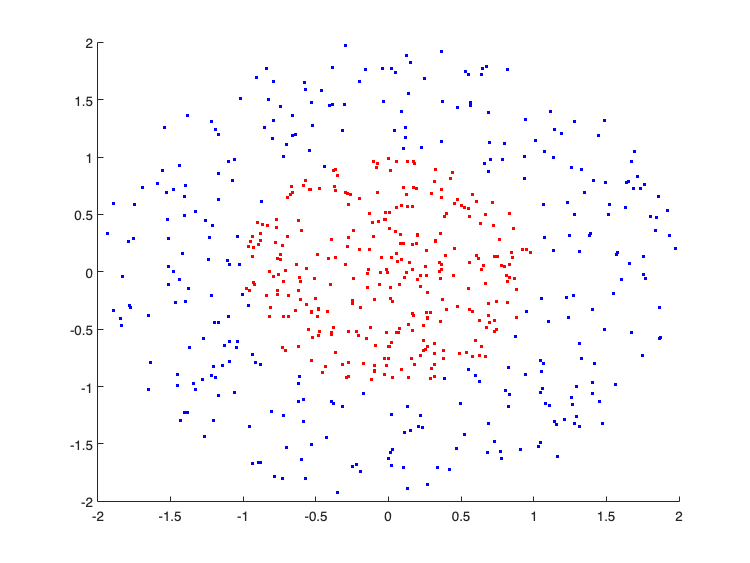

u = find(labels_tr == 1);
v = find(labels_tr == 2);
figure, hold on
plot(data_tr(u,1), data_tr(u, 2), 'r.')
plot(data_tr(v,1), data_tr(v, 2), 'b.')
hold off;

## Stratified sampling

rng('default') % Set seed for reproducibility
idx_fold1 = [];
idx_fold2 = [];
for nclass=1:2
    u = find(labels_tr == nclass);
    idx = randperm(numel(u));
    idx_fold1 = [idx_fold1; u(idx(1:round(numel(idx)/2)))];
    idx_fold2 = [idx_fold2; u(idx(1+round(numel(idx)/2):end))];
end

labels_fold1 = labels_tr(idx_fold1);
labels_fold2 = labels_tr(idx_fold2);

data_fold1 = data_tr(idx_fold1, :);
data_fold2 = data_tr(idx_fold2, :);

## Train level 1 classifier on fold 1

model_names = {'SVM_Gaussian', 'SVM_Polynomial', 'Decision_Tree', 'Naive_Bayes', 'Ensemble_Decision_Trees', 'Meta_Classifier_Scores', 'Meta_Classifier_Predictions'};
models_split = {};

% SVM with gaussian kernel
models_split{1} = fitcsvm(data_fold1, labels_fold1, 'KernelFunction', 'gaussian', 'KernelScale', 5);
% SVM with polynomial kernel
models_split{2} = fitcsvm(data_fold1, labels_fold1, 'KernelFunction', 'polynomial', 'KernelScale', 10);
% Decision tree
models_split{3} = fitctree(data_fold1, labels_fold1, 'SplitCriterion', 'gdi', 'MaxNumSplits', 20);
% Naive Bayes
models_split{4} = fitcnb(data_fold1, labels_fold1);
% Ensemble of decision trees
models_split{5} = fitcensemble(data_fold1, labels_fold1);

## Make predictions on fold 2

N = numel(models_split);
predictions_split = zeros(size(data_fold2, 1), N);
scores_split = zeros(size(data_fold2, 1), N);

% Predict using the first 5 models
for i = 1:5
    [prediction, score] = predict(models_split{i}, data_fold2);
    predictions_split(:, i) = prediction;
    scores_split(:, i) = score(:, 1);
end

## Assignment 1: Train the stacked classifier on fold 2 and compare accuracies between the 2 Meta Classifiers

% Assignment: compare the performance of the meta-classifier when trained on
% predictions (i.e. the predicted class) instead of the classification scores

rng('default');

% Train on Scores of split models
models_split{6} = fitcensemble(scores_split, labels_fold2, 'Method', 'Bag');
% Train on Predictions of split models
models_split{7} = fitcensemble(predictions_split, labels_fold2, 'Method', 'Bag');

N = numel(models_split);
accuracy_split = array2table(nan(1, 7), 'VariableNames', model_names);
predictions_split = zeros(size(data_te, 1), N);
scores_split = zeros(size(data_te, 1), N);

for i = 1:N
    if i < 6
        [prediction, score] = predict(models_split{i}, data_te); % First 5 models
    elseif i==6
        [prediction, score] = predict(models_split{i}, scores_split(:, 1:5)); % Stacked Classifiers trained on Scores
    else
        [prediction, score] = predict(models_split{i}, predictions_split(:, 1:5)); % Stacked Classifier trained on Predictions
    end
    predictions_split(:, i) = prediction;
    scores_split(:, i) = score(:, 1);
    accuracy_split{:, i} = numel(find(predictions_split(:, i) == labels_te)) / numel(labels_te);
end
accuracy_split

accuracy_split = 1×7 table
    SVM_Gaussian    SVM_Polynomial    Decision_Tree    Naive_Bayes    Ensemble_Decision_Trees    Meta_Classifier_Scores    Meta_Classifier_Predictions
    ____________    ______________    _____________    ___________    _______________________    ______________________    ___________________________

      0.86833           0.625            0.94833         0.97833              0.95333                     0.99                        0.97            


## Assignment 2: Training without split

% TBD: Compare the performance of the meta-classifier when the training
% split is not performed and the same data is used to train the level-1
% classifiers and meta-classifier

rng('default');

models_NO_split = {};
% SVM with gaussian kernel
models_NO_split{1} = fitcsvm(data_tr, labels_tr, 'KernelFunction', 'gaussian', 'KernelScale', 5);
% SVM with polynomial kernel
models_NO_split{2} = fitcsvm(data_tr, labels_tr, 'KernelFunction', 'polynomial', 'KernelScale', 10);
% Decision tree
models_NO_split{3} = fitctree(data_tr, labels_tr, 'SplitCriterion', 'gdi', 'MaxNumSplits', 20);
% Naive Bayes
models_NO_split{4} = fitcnb(data_tr, labels_tr);
% Ensemble of decision trees
models_NO_split{5} = fitcensemble(data_tr, labels_tr);

training_rows = size(data_tr, 1);

N = numel(models_NO_split);
predictions_NO_split = zeros(training_rows, N);
scores_NO_split = zeros(training_rows, N);

% Predict using the first 5 models
for i = 1:5
    [prediction, score] = predict(models_NO_split{i}, data_tr);
    predictions_NO_split(:, i) = prediction;
    scores_NO_split(:, i) = score(:, 1);
end
rng('default');

% Train on Scores of split models
models_NO_split{6} = fitcensemble(scores_NO_split, labels_tr, 'Method', 'Bag');
% Train on Predictions of split models
models_NO_split{7} = fitcensemble(predictions_NO_split, labels_tr, 'Method', 'Bag');

N = numel(models_NO_split);
accuracy_NO_split = array2table(nan(1, 7), 'VariableNames', model_names);
predictions_NO_split = zeros(training_rows, N);
scores_NO_split = zeros(training_rows, N);

for i = 1:N
    if i < 6
        [prediction, score] = predict(models_NO_split{i}, data_te); % First 5 models
    elseif i==6
        [prediction, score] = predict(models_NO_split{i}, scores_NO_split(:, 1:5)); % Stacked Classifiers trained on Scores
    else
        [prediction, score] = predict(models_NO_split{i}, predictions_NO_split(:, 1:5)); % Stacked Classifier trained on Predictions
    end
    predictions_NO_split(:, i) = prediction;
    scores_NO_split(:, i) = score(:, 1);
    accuracy_NO_split{:, i} = numel(find(predictions_NO_split(:, i) == labels_te)) / numel(labels_te);
end

accuracy_NO_split

accuracy_NO_split = 1×7 table
    SVM_Gaussian    SVM_Polynomial    Decision_Tree    Naive_Bayes    Ensemble_Decision_Trees    Meta_Classifier_Scores    Meta_Classifier_Predictions
    ____________    ______________    _____________    ___________    _______________________    ______________________    ___________________________

        0.9            0.63333           0.96667         0.99167              0.96833                     0.97                       0.96833          


accuracy_split

accuracy_split = 1×7 table
    SVM_Gaussian    SVM_Polynomial    Decision_Tree    Naive_Bayes    Ensemble_Decision_Trees    Meta_Classifier_Scores    Meta_Classifier_Predictions
    ____________    ______________    _____________    ___________    _______________________    ______________________    ___________________________

      0.86833           0.625            0.94833         0.97833              0.95333                     0.99                        0.97            
